# Configure Incremental Learning Options

Prepare an incremental regression learner by specifying a metrics warm-up period, during which the `updateMetricsAndFit` function only fits the model. Specify a metrics window size of 500 observations. Train the model by using SGD, and adjust the SGD batch size, learning rate, and regularization parameter. 

Load the robot arm data set. 

load robotarm
n = numel(ytrain);

For details on the data set, enter  `Description` at the command line.

Create an incremental linear model for regression. Configure the model as follows:

- Specify the SGD solver.

- Assume that these settings work well for the problem: a ridge regularization parameter value of 0.001, SGD batch size of 20, learning rate of 0.002, and half the width of the epsilon insensitive band for SVM of 0.05.

- Specify that the incremental fitting functions process the raw (unstandardized) predictor data.

- Specify a metrics warm-up period of 1000 observations.

- Specify a metrics window size of 500 observations.

- Track the epsilon insensitive loss, MSE, and mean absolute error (MAE) to measure the performance of the model. The software supports epsilon insensitive loss and MSE. Create an anonymous function that measures the absolute error of each new observation. Create a structure array containing the name `MeanAbsoluteError` and its corresponding function.

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
    'Metrics',{'epsiloninsensitive' 'mse' maemetric})

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [3×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'svm'


  Properties, Methods


`Mdl` is an `incrementalRegressionLinear` model object configured for incremental learning without an estimation period.

Fit the incremental model to the data by using the `updateMetricsAndFit` function. At each iteration:

- Simulate a data stream by processing a chunk of 50 observations. Note that the chunk size is different from SGD batch size.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store the estimated coefficient $\beta_{10}$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

% Preallocation
numObsPerChunk = 50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend;    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = Mdl.Beta(10);
end

`Mdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_{10}$ evolve during training, plot them on separate tiles.

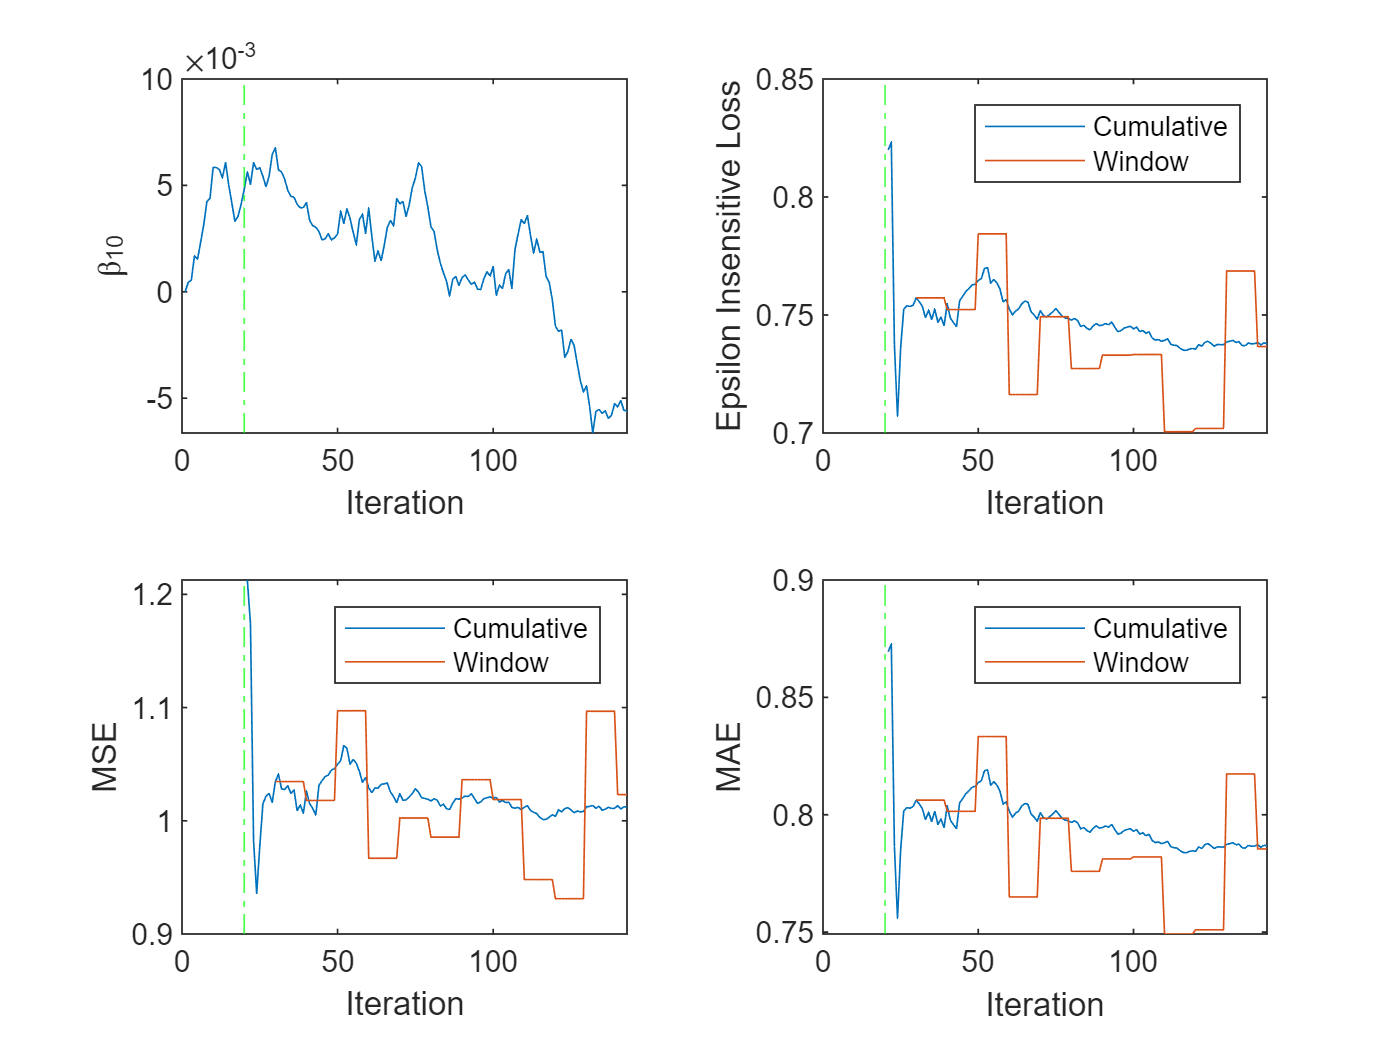

tiledlayout(2,2)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mse.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mae.Variables);
xlim([0 nchunk])
ylabel('MAE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mae.Properties.VariableNames)
xlabel('Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- Fit $\beta_{10}$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (10 iterations).

*Copyright 2020 The MathWorks, Inc.*